# Funciones escalares y vectoriales

#### Ejercicio 1

Graficación de una función escalar que representa la temperatura como variable dependiente del tiempo.

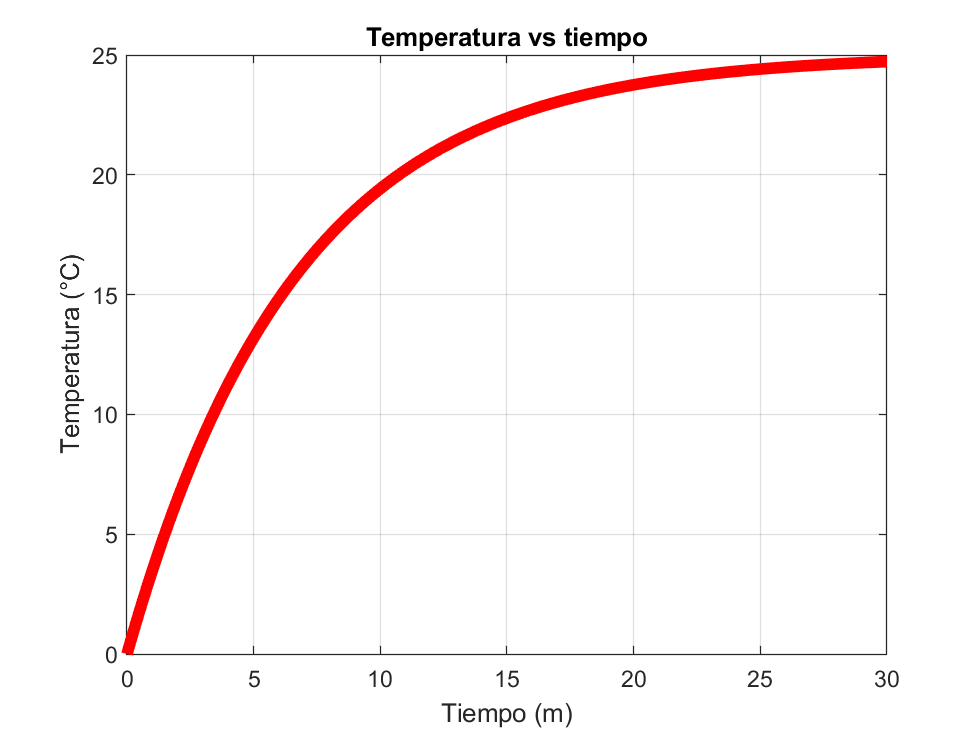

t = 0:0.01:30;              % Valores de tiempo
T = 25 - 25*exp(-0.15*t);   % Valores de temperatura

% Gráfica de tiempo vs temperatura
plot(t, T, 'r-', 'LineWidth', 5)
xlabel('Tiempo (m)')
ylabel('Temperatura (°C)')
title('Temperatura vs tiempo')
grid on  

#### Ejercicio 2

Graficación de una función escalar que representa la temperatura de un objeto de dimensiones 10 x 4 en diferentes puntos. 

La función **contourf** permite graficar valores escalares sobre una superficie X-Y. Los valores para cada punto se representan por colores.

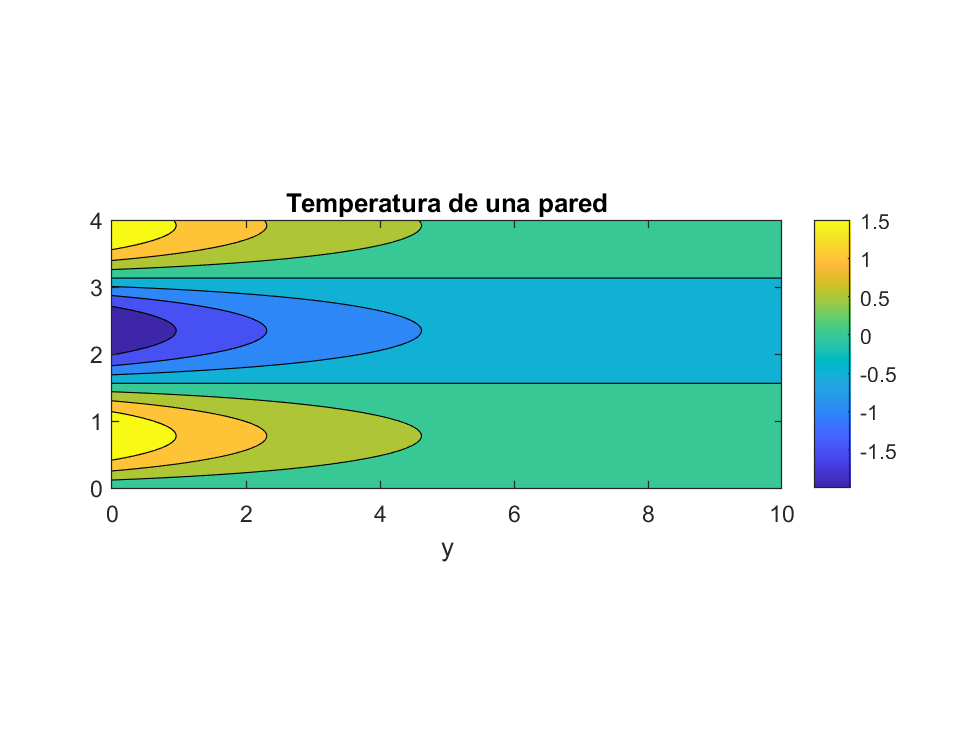

xl = linspace(0,10,100);        % Valores de x que vamos a evaluar
yl = linspace(0,4,100);         % Valores de y que vamos a evaluar
[x, y] = meshgrid(xl, yl);      % Retícula de puntos
T = 2*exp(-0.3*x).*sin(2*y);    % Valores de temperatura

% Gráfica de contornos para la temperatura del objeto
contourf(x, y, T)   % Gráfica de contornos
colorbar            % Agrega la barra de colores
axis equal          % Forza que los ejes tengan la misma escala
xlabel('x')
xlabel('y')
title('Temperatura de una pared')

#### Ejercicio 3

Función vectorial en el plano X-Y. 

La función **quiver** permite dibujar vectores en el plano. A esta función se le pasan las componentes "u" y "v" de los vectores a dibujar para cada valor "x" "y". Los valores con "**nan**" se ignoran.

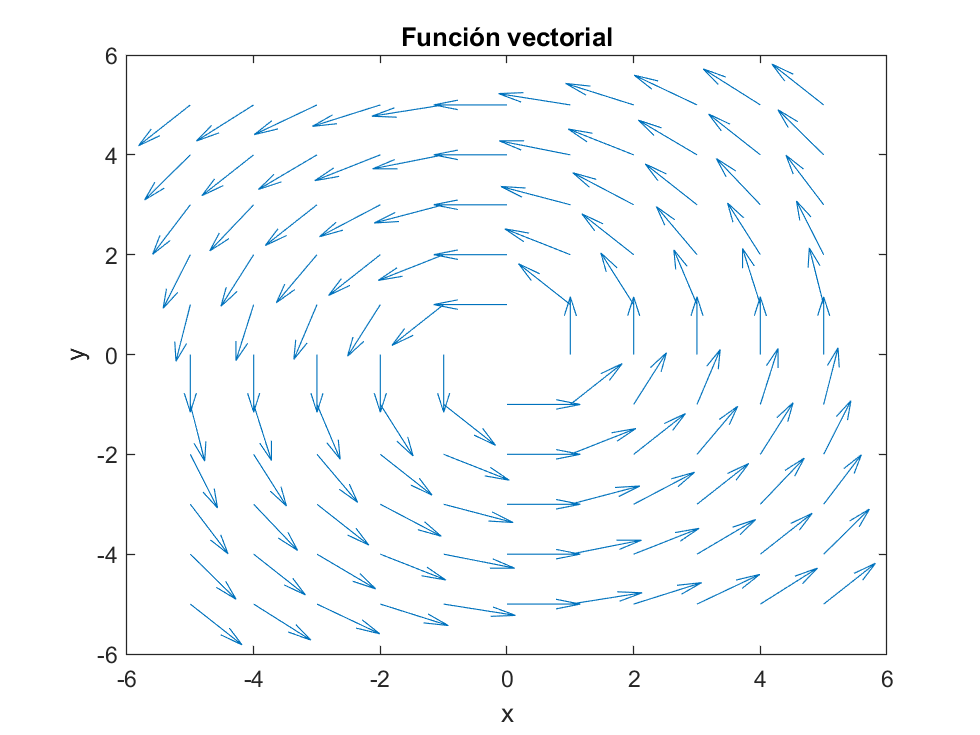

xl = linspace(-5, 5, 11);   % Valores de x que vamos a evaluar
yl = linspace(-5, 5, 11);   % Valores de y que vamos a evaluar
[x, y] = meshgrid(xl, yl);  % Retícula de puntos

u = -y./sqrt(x.^2 + y.^2);  % Componente en x de la función vectorial
v = +x./sqrt(x.^2 + y.^2);  % Componente en y de la función vectorial

% Gráfica de la función vectorial
quiver(x, y, u, v)
xlabel('x')
ylabel('y')
title('Función vectorial')

Para generar las flechas, la función quiver escala los vectores para optimizar la visualización. La propiedad '**AutoScaleFactor**' permite controlar dicho escalado. Un valor de 0 indica que no se escala y se traza tal como se indica en los valores de los vectores.

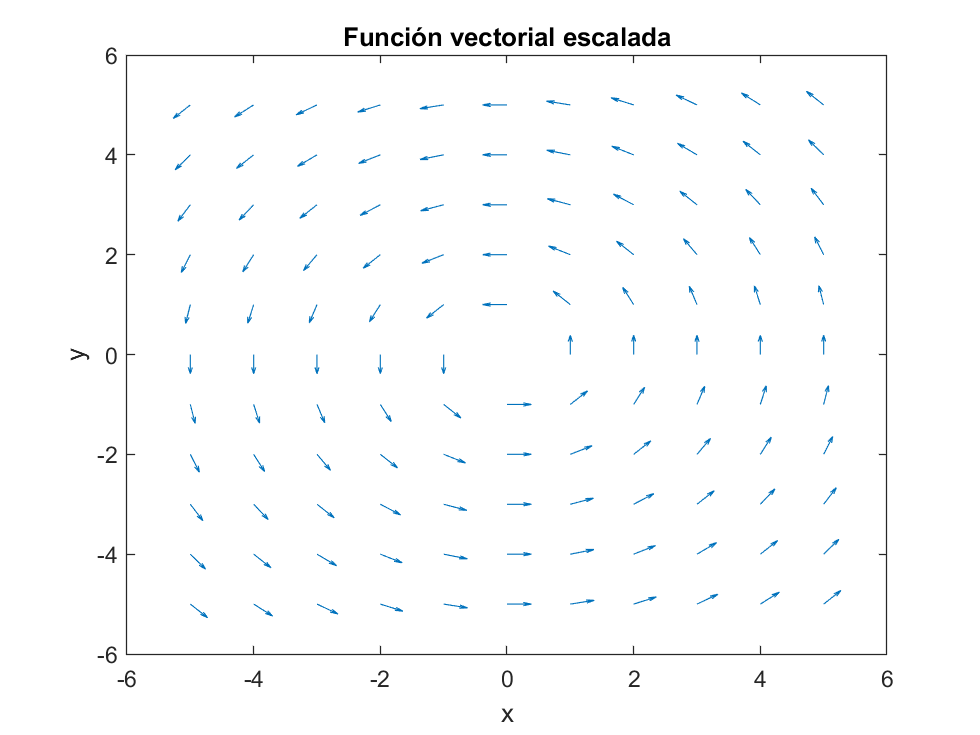

% Gráfica de la función vectorial con vectores escalados por un factor dado
quiver(x, y, u, v, 'AutoScaleFactor', 0.3)
xlabel('x')
ylabel('y')
title('Función vectorial escalada')

No es necesario indicar la propiedad '**AutoScaleFactor**' para el escalado. El argumento después de los vectores está reservado para ello.

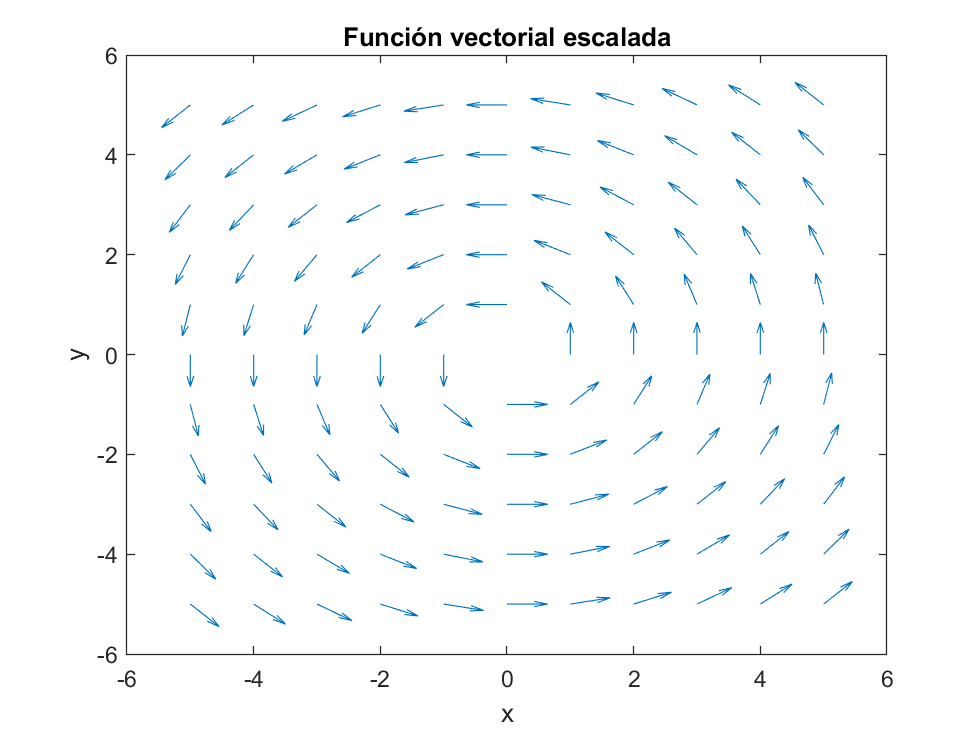

% Gráfica de la función vectorial con vectores escalados por un factor dado
quiver(x, y, u, v, 0.5)
xlabel('x')
ylabel('y')
title('Función vectorial escalada')

Es posible cambiar el ancho de los trazos de las flechas y el color con las propiedades **LineWidth** y **Color**.

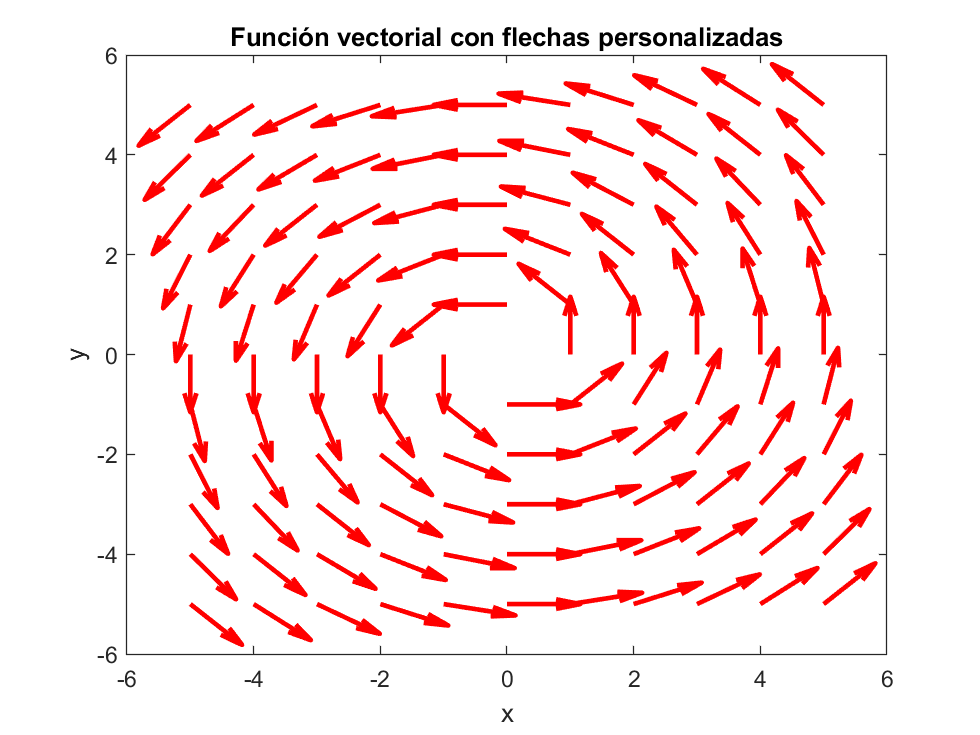

% Personalización del trazo de las flechas
quiver(x, y, u, v, 'Color', 'r', 'LineWidth', 2)
xlabel('x')
ylabel('y')
title('Función vectorial con flechas personalizadas')

#### Ejercicio 4

Campo gravitación de la tierra en el espacio. 

La función **quiver3** permite dibujar vectores en el espacio. Después de las componentes de los vectores a dibujar, se puede indicar la escala de los vectores. 0 significa sin escala, 1 significa con escala automática.

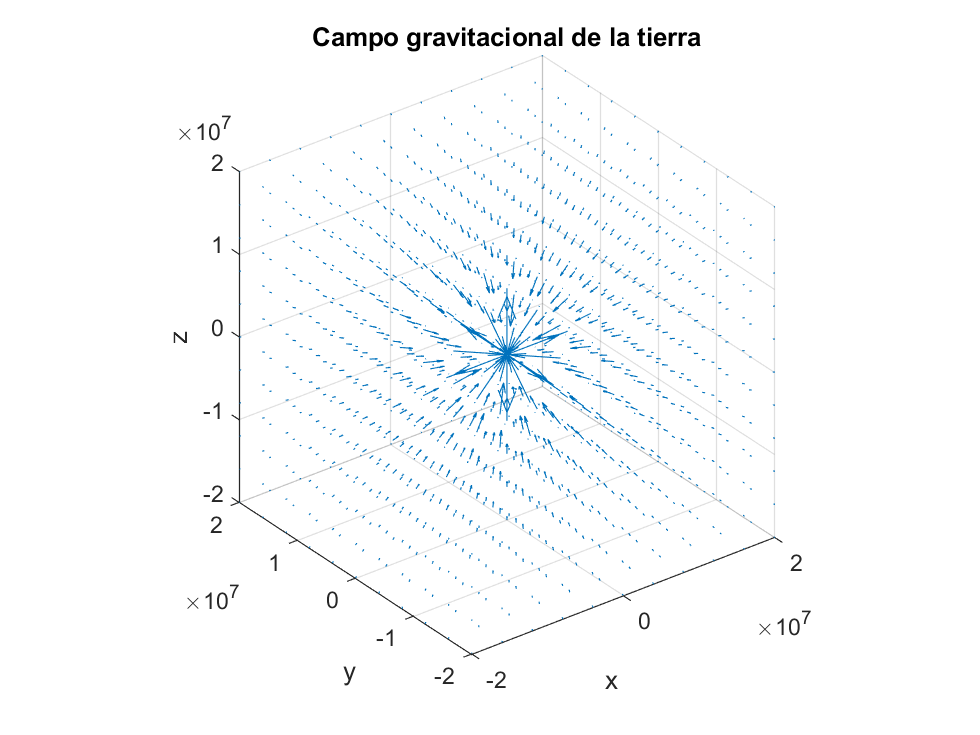

xl = linspace(-20000e3, 20000e3, 11);  % Valores de x que vamos a evaluar
yl = linspace(-20000e3, 20000e3, 11);  % Valores de y que vamos a evaluar
zl = linspace(-20000e3, 20000e3, 11);  % Valores de z que vamos a evaluar
[x, y, z] = meshgrid(xl, yl, zl);      % Retícula de puntos

% Calcula campo vectorial
k = -3.9858e14;
u = k*x./((x.^2 + y.^2 + z.^2).^1.5);  % Componente en x de la función vectorial
v = k*y./((x.^2 + y.^2 + z.^2).^1.5);  % Componente en y de la función vectorial
w = k*z./((x.^2 + y.^2 + z.^2).^1.5);  % Componente en z de la función vectorial

% Gráfica de la función vectorial
quiver3(x, y, z, u, v, w, 3)
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
title('Campo gravitacional de la tierra')

Para mejorar la representación del campo, es posible seleccionar puntos que no sean en forma de retícula. Por ejemplo, es posible escoger definir puntos que sean esferas concéntricas alrededor de la tierra para que el campo se represente de manera radial.

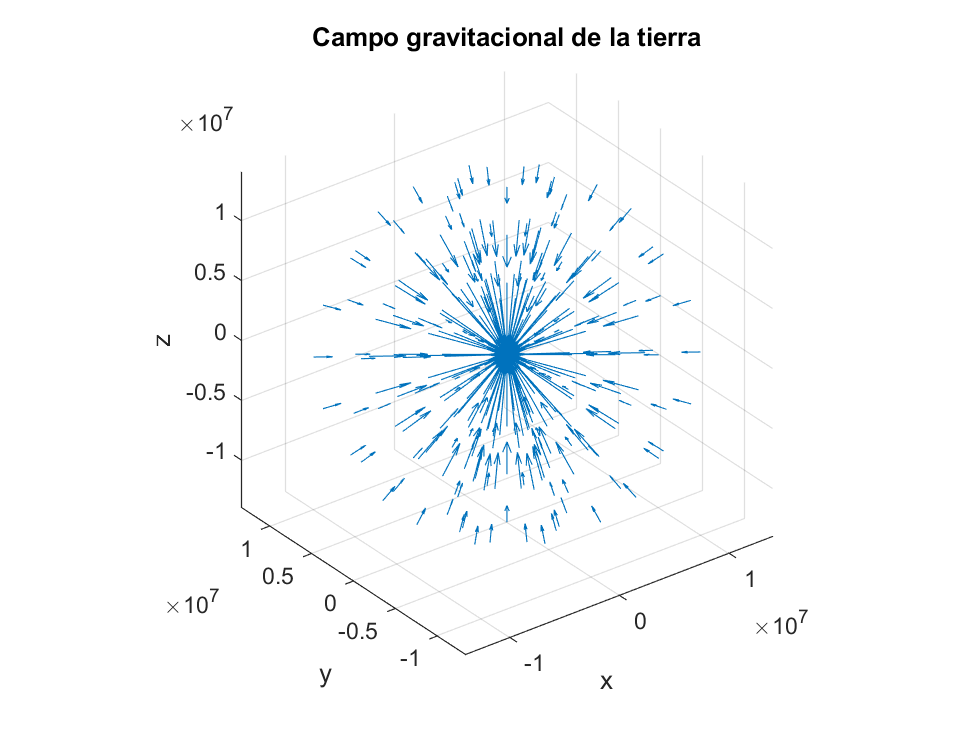

[xu,yu,zu] = sphere(10);    % Esfera de radio unitario

% Define 3 cascarones de radios 6000km, 9000km y 12000km
x = [6000e3*xu(:); 10000e3*xu(:); 14000e3*xu(:)];
y = [6000e3*yu(:); 10000e3*yu(:); 14000e3*yu(:)];
z = [6000e3*zu(:); 10000e3*zu(:); 14000e3*zu(:)];

% Calcula campo vectorial
k = -3.9858e14;
u = k*x./((x.^2 + y.^2 + z.^2).^1.5);  % Componente en x de la función vectorial
v = k*y./((x.^2 + y.^2 + z.^2).^1.5);  % Componente en y de la función vectorial
w = k*z./((x.^2 + y.^2 + z.^2).^1.5);  % Componente en z de la función vectorial

% Gráfica de la función vectorial
quiver3(x, y, z, u, v, w, 3)
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
title('Campo gravitacional de la tierra')